# ModelB SM with dampening integrator Model

Model B to Single Machine Model, to model a weak grid with finite inertia. Based on Gomez's eqs 10.3-10.7 for both machines, grid is motoring, grid swing eq (5) may have additional damping term commented out. CURRENTLY NO DISTURBANCE/STEP-CHANGE, TBC.

### **Constants**

f  = 50;
ws = 2*pi*f;  %chosen reference rotational velocity, rad/s

% Machine 1 Network (Keep this part)
Xd1 = 0.1;
XT1 = 0.05;
X1 = Xd1 + XT1;

% Model B / Inverter Parameters (Replaces Machine 1 physics)
Pref_init  = 1;


% Mohammed et al. inverter bases
Moh.Sbase = 5e6;
Moh.VLL_rms = 690;
Moh.Vbase = sqrt(2/3)*Moh.VLL_rms;

% Mohammed et al. VSG parameters
Moh.Dp = 1.273e6;
Moh.J = 4052;
Moh.nq = 1.5e-5;
Moh.Kiq = 1e-4;

% Convert to per-unit values used by this model
Dp = Moh.Dp/Moh.Sbase;
J = Moh.J/Moh.Sbase;
nq = Moh.nq*Moh.Sbase/Moh.Vbase;
Kiq = Moh.Kiq*Moh.Sbase/Moh.Vbase;


CurrentLimiter.Enable = true;
CurrentLimiter.Imax = 1.2;     % pu, provisional literature-based value
CurrentLimiter.Eps = 1e-9;

% Base values for Machine 2 (Since we deleted D1 and H1)
D1_base = 0.1; 
H1_base = 3;

% Machine 2 / finite grid
D2 = 4*D1_base;
H2 = 4*H1_base;
% AEMO 3.2.4 Test 16 grid strength
SCR = 3;

% Equivalent external grid reactance
Xs = 1/SCR;

% Preserve original XL:X2 ratio of 3:1
XL = 0.75*Xs;
X2 = 0.25*Xs;


% Grid-side load integrator
Ki_grid = 0.5;

% Initial grid-side absorbed power
Pload0 = Pref_init;

% Used only for calculating initial SM2 equilibrium
Pm2_initial = -Pload0;

% Network
XTot = X1 + XL + X2;

% AEMO Test 16 fault impedance
% Test 16 specifies Zf = Zs.
% Resistance is neglected, therefore Xf = Xs.

Xf = Xs;

% AEMO 3.2.4 Test 16 fault timing
Fault_t_on = 5;
Fault_t_off = 5.43;

Fault_ramp = 0.02;

FaultScale = @(t) max(0,min([1,(t-Fault_t_on)/Fault_ramp,(Fault_t_off-t)/Fault_ramp]));



### Design Parameters

% K1 = 1.2;  %Gen Gain Constant
% K2 = 4*K1; %Grid Gain Constant

### Specified Inputs

% Specified Inputs
K2 = 4*1.2;          % Grid Gain Constant
V2o = 1;

V1o = 1;

% No active power reference disturbance in this test
Pref_step = @(t) Pref_init*ones(size(t));

% % Check that a power-flow solution exists
% s1 = Pm*XL/(Vinf*V1o);
% s2 = Pm*XL/(Vinf*V1o_after);
% if abs(s1) > 1 && abs(s2) >1
%     error('No steady-state equilibrium exists for this Pm and V1o.');
% end

### Initial Conditions

% The following are for initial conditions at a steady state equilibrium
domega10 = 0;
domega20 = 0;

V2PCCmag0 = V2o;
delta2PCC0 = 0;

% AEMO Test 16 initial operating condition:
% P = 1 pu
% Q = 0 pu at PCC1

arg = 2*Pref_init*XL/(V2PCCmag0^2);

if abs(arg) > 1
    error('No P = 1 pu, Q = 0 pu equilibrium exists for the selected grid reactance.');
end

delta1PCC0 = 0.5*asin(arg);

V1PCCmag0 = V2PCCmag0*cos(delta1PCC0);

Q12 = 0;

Q21 = (V2PCCmag0^2 - V2PCCmag0*V1PCCmag0*cos(delta2PCC0-delta1PCC0))/XL;

Qref = 0;

E10 = hypot(Pref_init*X1/V1PCCmag0, V1PCCmag0 + Q12*X1/V1PCCmag0);
delta10 = delta1PCC0 + atan2(Pref_init*X1/V1PCCmag0, V1PCCmag0 + Q12*X1/V1PCCmag0);
E20 = hypot(Pm2_initial*X2/V2PCCmag0, ...
    V2PCCmag0 + Q21*X2/V2PCCmag0);

delta20 = delta2PCC0 + atan2(Pm2_initial*X2/V2PCCmag0, ...
    V2PCCmag0 + Q21*X2/V2PCCmag0);

% State 3 is now the RPC Integrator state, initialized to steady state
x3_0 = E10 - V1o;

x0 = [delta10;
      domega10;
      x3_0;
      delta20;
      domega20;
      E20;
      Pload0;
      V1PCCmag0;
      delta1PCC0;
      V2PCCmag0;
      delta2PCC0];

% Helper functions for local PCC power and dynamic E1
Ppcc = @(x) (x(8)*x(10)/XL)*sin(x(9)-x(11));

Qpcc = @(x) (x(8)^2 - x(8)*x(10)*cos(x(9)-x(11)))/XL;

Qfault = @(t,x) FaultScale(t)*(x(8)^2/Xf);

% Total reactive power supplied by Model B during the fault
Qplant = @(t,x) Qpcc(x) + Qfault(t,x);

% Actual electrical power of SM2
Pe2 = @(x) (x(6)*x(10)/X2)*sin(x(4)-x(11));

% Model B voltage command
E1 = @(t,x) V1o + nq*(Qref - Qplant(t,x)) + x(3);

%% ============================================================
% CONVERTER CURRENT LIMITER
% ============================================================

E1cmd_complex = @(t,x) E1(t,x)*exp(1j*x(1));

V1_complex_fun = @(x) x(8)*exp(1j*x(9));

I1cmd_complex = @(t,x) (E1cmd_complex(t,x) - V1_complex_fun(x))/(1j*X1);

if CurrentLimiter.Enable
    CurrentScale = @(t,x) min(1,CurrentLimiter.Imax/max(abs(I1cmd_complex(t,x)),CurrentLimiter.Eps));
else
    CurrentScale = @(t,x) 1;
end

E1actual_complex = @(t,x) V1_complex_fun(x) + CurrentScale(t,x)*(E1cmd_complex(t,x) - V1_complex_fun(x));

E1actual_mag = @(t,x) abs(E1actual_complex(t,x));

E1actual_ang = @(t,x) angle(E1actual_complex(t,x));

%% ============================================================
% CURRENT LIMIT AWARE OUTER CONTROL
% ============================================================

LimiterActive = @(t,x) CurrentScale(t,x) < 0.999;


Perror_raw = @(t,x) Pref_step(t) - Ppcc(x);

Qerror_raw = @(t,x) Qref - Qplant(t,x);

Perror_eff = @(t,x) (1-double(LimiterActive(t,x)))*Perror_raw(t,x);

### State Space Equations and Solve

DynamicsEqs = @(t,x)[

    x(2);                                                         % 1: delta1

    (1/(J*ws))*(Perror_eff(t,x) - Dp*x(2));              % 2: Model B APC

    Kiq*(Qref - Qplant(t,x));                                   % 3: RPC integrator

    x(5);                                                        % 4: delta2

    (ws/(2*H2))*(-x(7) - Pe2(x) - D2*x(5));                     % 5: SM2 swing

    K2*(V2o - x(10));                                           % 6: SM2 voltage

    Ki_grid*x(5);                                                % 7: Grid load integrator

    (E1actual_mag(t,x)*x(8)/X1)*sin(E1actual_ang(t,x)-x(9)) - Ppcc(x);   % 8: PCC1 P balance

    (E1actual_mag(t,x)*x(8)*cos(E1actual_ang(t,x)-x(9)) - x(8)^2)/X1 - Qpcc(x) - Qfault(t,x); % 9: PCC1 Q balance

    (x(6)*x(10)/X2)*sin(x(4)-x(11)) - (x(10)*x(8)/XL)*sin(x(11)-x(9)); % 10

    (x(6)*x(10)*cos(x(4)-x(11)) - x(10)^2)/X2 - (x(10)^2 - x(10)*x(8)*cos(x(11)-x(9)))/XL % 11
];

Mass = diag([1 1 1 1 1 1 1 0 0 0 0]);
options = odeset('Mass',Mass,'MaxStep',0.001,'RelTol',1e-7,'AbsTol',1e-9);

tspan = [0 15];

[t,x] = ode15s(DynamicsEqs,tspan,x0,options);
xn_end = x(end,:).';

fprintf('\nLAST SOLVED POINT\n');


LAST SOLVED POINT


fprintf('t = %.9f s\n',t(end));

t = 15.000000000 s


fprintf('delta1 = %.6f rad\n',xn_end(1));

delta1 = 0.421203 rad


fprintf('domega1 = %.6f rad/s\n',xn_end(2));

domega1 = 0.000011 rad/s


fprintf('x3 = %.6f\n',xn_end(3));

x3 = -0.021671


fprintf('V1PCC = %.6f pu\n',xn_end(8));

V1PCC = 0.965926 pu


fprintf('delta1PCC = %.6f rad\n',xn_end(9));

delta1PCC = 0.261797 rad


fprintf('|Icmd| = %.6f pu\n',abs(I1cmd_complex(t(end),xn_end)));

|Icmd| = 1.035278 pu


fprintf('Limiter scale = %.9f\n',CurrentScale(t(end),xn_end));

Limiter scale = 1.000000000


fprintf('Ppcc = %.6f pu\n',Ppcc(xn_end));

Ppcc = 1.000002 pu


fprintf('Qplant = %.6f pu\n',Qplant(t(end),xn_end));

Qplant = 0.000000 pu


fprintf('delta1-deltaPCC = %.3f deg\n',(xn_end(1)-xn_end(9))*180/pi);

delta1-deltaPCC = 9.133 deg



FaultStatus = arrayfun(FaultScale,t);

### Calculating PG and QG at each point in time

% Use x vector to get P, Q
delta1  = x(:,1);
domega1 = x(:,2);
x3      = x(:,3);

delta2  = x(:,4);
domega2 = x(:,5);
E2      = x(:,6);

Pload   = x(:,7);

V1PCCmag  = x(:,8);
delta1PCC = x(:,9);

V2PCCmag  = x(:,10);
delta2PCC = x(:,11);

PG      = zeros(length(t),1);
QG      = zeros(length(t),1);

I1mag = zeros(length(t),1);
Ip = zeros(length(t),1);
Iq = zeros(length(t),1);


Psource = zeros(length(t),1);
Qsource = zeros(length(t),1);

E1_plot = zeros(length(t),1);

for n = 1:length(t)
    
    PG(n) = (V1PCCmag(n)*V2PCCmag(n)/XL)*sin(delta1PCC(n)-delta2PCC(n)); % Active power from PCC1 to PCC2
    
    QG(n) = (V1PCCmag(n)^2/XL) - (V1PCCmag(n)*V2PCCmag(n)/XL)*cos(delta1PCC(n)-delta2PCC(n)); %Reactive power from PCC1 to PCC2
end

### Plot -WHICH PLOTS WE WANT TBC

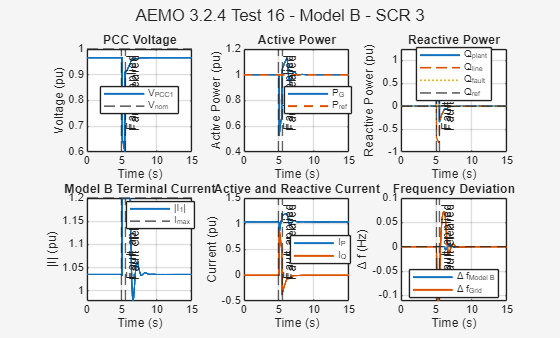

%% ============================================================
% CALCULATING OUTPUTS
% ============================================================

delta1  = x(:,1);
domega1 = x(:,2);
x3      = x(:,3);

delta2  = x(:,4);
domega2 = x(:,5);
E2      = x(:,6);

Pload = x(:,7);

V1PCCmag  = x(:,8);
delta1PCC = x(:,9);

V2PCCmag  = x(:,10);
delta2PCC = x(:,11);


%% Preallocate output variables

N = length(t);

PG = zeros(N,1);
QG = zeros(N,1);

Qfault_plot = zeros(N,1);
Qplant_plot = zeros(N,1);

I1mag = zeros(N,1);
Ip = zeros(N,1);
Iq = zeros(N,1);
I1cmd_mag = zeros(N,1);
DeltaAngle = zeros(N,1);

Psource = zeros(N,1);
Qsource = zeros(N,1);

E1_cmd_plot = zeros(N,1);
E1_actual_plot = zeros(N,1);

LimiterScale = zeros(N,1);


%% Calculate network and converter outputs

for n = 1:N

    xn = x(n,:).';

    I1cmd_n = I1cmd_complex(t(n),xn);

I1cmd_mag(n) = abs(I1cmd_n);

DeltaAngle(n) = atan2(sin(delta1(n)-delta1PCC(n)),cos(delta1(n)-delta1PCC(n)));

    % Active power from PCC1 toward PCC2
    PG(n) = (V1PCCmag(n)*V2PCCmag(n)/XL)*sin(delta1PCC(n)-delta2PCC(n));

    % Reactive power from PCC1 toward PCC2
    QG(n) = (V1PCCmag(n)^2/XL) - (V1PCCmag(n)*V2PCCmag(n)/XL)*cos(delta1PCC(n)-delta2PCC(n));

    % Reactive power supplied to fault
    Qfault_plot(n) = FaultScale(t(n))*V1PCCmag(n)^2/Xf;

    % Total reactive power supplied by Model B
    Qplant_plot(n) = QG(n) + Qfault_plot(n);

    % Commanded Model B internal voltage
    E1_cmd_plot(n) = E1(t(n),xn);

    % Current limiter scale
    LimiterScale(n) = CurrentScale(t(n),xn);

    % Actual converter voltage after current limiting
    E1_actual_complex_n = E1actual_complex(t(n),xn);

    E1_actual_plot(n) = abs(E1_actual_complex_n);

    % PCC voltage phasor
    V1_complex = V1PCCmag(n)*exp(1j*delta1PCC(n));

    % Actual converter current
    I1_complex = (E1_actual_complex_n - V1_complex)/(1j*X1);

    I1mag(n) = abs(I1_complex);

    % Actual converter complex power
    S1_complex = V1_complex*conj(I1_complex);

    Psource(n) = real(S1_complex);
    Qsource(n) = imag(S1_complex);

    % Active and reactive current components
    if V1PCCmag(n) > 1e-6
        Ip(n) = Psource(n)/V1PCCmag(n);
        Iq(n) = Qsource(n)/V1PCCmag(n);
    else
        Ip(n) = 0;
        Iq(n) = 0;
    end

end


%% ============================================================
% REFERENCE SIGNALS
% ============================================================

Pref_plot = Pref_step(t);


%% ============================================================
% MAIN AEMO TEST RESULTS
% ============================================================

figure('Visible','on');


%% 1. PCC Voltage

subplot(2,3,1);

plot(t,V1PCCmag,'LineWidth',1.5);

hold on;

yline(V1o,'--','LineWidth',1.2);

xline(Fault_t_on,'--','Fault applied');
xline(Fault_t_off,'--','Fault cleared');

xlabel('Time (s)');
ylabel('Voltage (pu)');

legend('V_{PCC1}','V_{nom}','Location','best');

title('PCC Voltage');

grid on;


%% 2. Active Power

subplot(2,3,2);

plot(t,PG,'LineWidth',1.5);

hold on;

plot(t,Pref_plot,'--','LineWidth',1.5);

xline(Fault_t_on,'--','Fault applied');
xline(Fault_t_off,'--','Fault cleared');

xlabel('Time (s)');
ylabel('Active Power (pu)');

legend('P_G','P_{ref}','Location','best');

title('Active Power');

grid on;


%% 3. Reactive Power

subplot(2,3,3);

plot(t,Qplant_plot,'LineWidth',1.5);

hold on;

plot(t,QG,'--','LineWidth',1.2);
plot(t,Qfault_plot,':','LineWidth',1.2);

yline(Qref,'--','LineWidth',1.2);

xline(Fault_t_on,'--','Fault applied');
xline(Fault_t_off,'--','Fault cleared');

xlabel('Time (s)');
ylabel('Reactive Power (pu)');

legend('Q_{plant}','Q_{line}','Q_{fault}','Q_{ref}','Location','best');

title('Reactive Power');

grid on;


%% 4. Converter Terminal Current

subplot(2,3,4);

plot(t,I1mag,'LineWidth',1.5);

hold on;

yline(CurrentLimiter.Imax,'--','I_{max}','LineWidth',1.2);

xline(Fault_t_on,'--','Fault applied');
xline(Fault_t_off,'--','Fault cleared');

xlabel('Time (s)');
ylabel('|I| (pu)');

legend('|I_1|','I_{max}','Location','best');

title('Model B Terminal Current');

grid on;


%% 5. Active and Reactive Current

subplot(2,3,5);

plot(t,Ip,'LineWidth',1.5);

hold on;

plot(t,Iq,'LineWidth',1.5);

xline(Fault_t_on,'--','Fault applied');
xline(Fault_t_off,'--','Fault cleared');

xlabel('Time (s)');
ylabel('Current (pu)');

legend('I_P','I_Q','Location','best');

title('Active and Reactive Current');

grid on;


%% 6. Frequency Deviation

subplot(2,3,6);

plot(t,domega1/(2*pi),'LineWidth',1.5);

hold on;

plot(t,domega2/(2*pi),'LineWidth',1.5);

yline(0,'--','LineWidth',1.0);

xline(Fault_t_on,'--','Fault applied');
xline(Fault_t_off,'--','Fault cleared');

xlabel('Time (s)');
ylabel('\Delta f (Hz)');

legend('\Delta f_{Model B}','\Delta f_{Grid}','Location','best');

title('Frequency Deviation');

grid on;


sgtitle('AEMO 3.2.4 Test 16 - Model B - SCR 3');

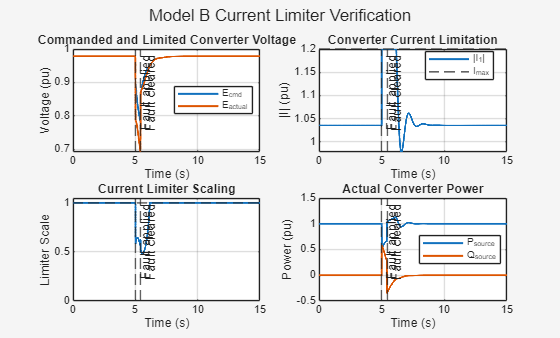



%% ============================================================
% CURRENT LIMITER VERIFICATION
% ============================================================

figure('Visible','on');


%% 1. Commanded and Actual Converter Voltage

subplot(2,2,1);

plot(t,E1_cmd_plot,'LineWidth',1.5);

hold on;

plot(t,E1_actual_plot,'LineWidth',1.5);

xline(Fault_t_on,'--','Fault applied');
xline(Fault_t_off,'--','Fault cleared');

xlabel('Time (s)');
ylabel('Voltage (pu)');

legend('E_{cmd}','E_{actual}','Location','best');

title('Commanded and Limited Converter Voltage');

grid on;


%% 2. Converter Current

subplot(2,2,2);

plot(t,I1mag,'LineWidth',1.5);

hold on;

yline(CurrentLimiter.Imax,'--','I_{max}','LineWidth',1.2);

xline(Fault_t_on,'--','Fault applied');
xline(Fault_t_off,'--','Fault cleared');

xlabel('Time (s)');
ylabel('|I| (pu)');

legend('|I_1|','I_{max}','Location','best');

title('Converter Current Limitation');

grid on;


%% 3. Current Limiter Scaling

subplot(2,2,3);

plot(t,LimiterScale,'LineWidth',1.5);

hold on;

yline(1,'--','LineWidth',1.0);

xline(Fault_t_on,'--','Fault applied');
xline(Fault_t_off,'--','Fault cleared');

xlabel('Time (s)');
ylabel('Limiter Scale');

ylim([0 1.05]);

title('Current Limiter Scaling');

grid on;


%% 4. Actual Converter Power

subplot(2,2,4);

plot(t,Psource,'LineWidth',1.5);

hold on;

plot(t,Qsource,'LineWidth',1.5);

xline(Fault_t_on,'--','Fault applied');
xline(Fault_t_off,'--','Fault cleared');

xlabel('Time (s)');
ylabel('Power (pu)');

legend('P_{source}','Q_{source}','Location','best');

title('Actual Converter Power');

grid on;


sgtitle('Model B Current Limiter Verification');

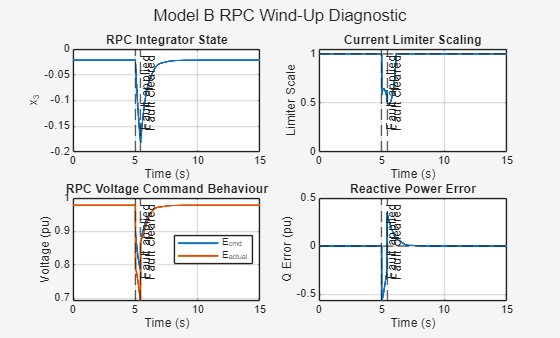



%% ============================================================
% RPC INTEGRATOR / ANTI-WINDUP DIAGNOSTIC
% ============================================================

figure('Visible','on');


%% 1. RPC Integrator State

subplot(2,2,1);

plot(t,x3,'LineWidth',1.5);

hold on;

xline(Fault_t_on,'--','Fault applied');
xline(Fault_t_off,'--','Fault cleared');

xlabel('Time (s)');
ylabel('x_3');

title('RPC Integrator State');

grid on;


%% 2. Current Limiter Scaling

subplot(2,2,2);

plot(t,LimiterScale,'LineWidth',1.5);

hold on;

yline(1,'--','LineWidth',1.0);

xline(Fault_t_on,'--','Fault applied');
xline(Fault_t_off,'--','Fault cleared');

xlabel('Time (s)');
ylabel('Limiter Scale');

ylim([0 1.05]);

title('Current Limiter Scaling');

grid on;


%% 3. Commanded and Actual Converter Voltage

subplot(2,2,3);

plot(t,E1_cmd_plot,'LineWidth',1.5);

hold on;

plot(t,E1_actual_plot,'LineWidth',1.5);

xline(Fault_t_on,'--','Fault applied');
xline(Fault_t_off,'--','Fault cleared');

xlabel('Time (s)');
ylabel('Voltage (pu)');

legend('E_{cmd}','E_{actual}','Location','best');

title('RPC Voltage Command Behaviour');

grid on;


%% 4. Reactive Power Error

Qerror_plot = Qref - Qplant_plot;

subplot(2,2,4);

plot(t,Qerror_plot,'LineWidth',1.5);

hold on;

yline(0,'--','LineWidth',1.0);

xline(Fault_t_on,'--','Fault applied');
xline(Fault_t_off,'--','Fault cleared');

xlabel('Time (s)');
ylabel('Q Error (pu)');

title('Reactive Power Error');

grid on;


sgtitle('Model B RPC Wind-Up Diagnostic');


figure('Visible','on');

subplot(3,1,1);
plot(t,I1cmd_mag,'LineWidth',1.5);
hold on;
plot(t,I1mag,'LineWidth',1.5);
yline(CurrentLimiter.Imax,'--','I_{max}');
xlabel('Time (s)');
ylabel('Current (pu)');
legend('|I_{cmd}|','|I_{actual}|','I_{max}');
title('Command Current vs Limited Current');
grid on;

subplot(3,1,2);
plot(t,LimiterScale,'LineWidth',1.5);
xlabel('Time (s)');
ylabel('Limiter Scale');
title('Limiter Scale');
grid on;

subplot(3,1,3);
plot(t,DeltaAngle*180/pi,'LineWidth',1.5);
xlabel('Time (s)');
ylabel('\delta_1-\delta_{PCC1} (deg)');
title('Source to PCC Angle Difference');
grid on;